# Divergent Neural Processing of Self-Referential Stimuli in Orbitofrontal and Ventromedial Cortex Populations 

% -*- UFT -*-
% Author: behira
% behzadiravani@gmail.com
% loading the data
clc
clear 
data = readtable('data\stimlock.tsv', FileType='text'); % reading the tabular data

## Subject and Experimental Condition

% create report object 
report = stat_report(data, 'data\BHV.json', 'data\FrontalEcogvsSeeg.json'); % stat_report instance
% print some info
Uniq_id = report.report("num_indiv");

The total number of pt is: 22

 

report.report("number_total_elec"); % statistical summary of the number of electrodes

The total number of elec is: 253, in total patients 22
 mean (std) # elec: 11.50(10.60), range =  [1,38]

 

## Behavioral Data

Finding out how many trials per conditions have been performed on average. 

report.report("number_trials"); % statistical summary of the number of trials per condition 

EP # trails: mean (std): 24 (1.2)
SJ # trails: mean (std): 24 (1.9)
MTH # trails: mean (std): 39 (1.7)


report.report("number_true_false") % statistical summary of the number of trials responded with true and false

EP true # trails replied with true: mean (std): 9 (4), range = [4,22]
EP false # trails replied with true: mean (std): 15 (4), range = [4,21]
SJ true # trails replied with true: mean (std): 16 (3), range = [8,23]
SJ false # trails replied with true: mean (std): 8 (3), range = [3,14]
MTH true # trails replied with true: mean (std): 21 (4), range = [15,31]
MTH false # trails replied with true: mean (std): 16 (3), range = [9,20]


ans = struct with fields:
     true: {[9 4 4 22]  [16 3 8 23]  [21 4 15 31]}
    false: {[15 4 4 21]  [8 3 3 14]  [16 3 9 20]}


report.report("reaction_time") % statistical summary of the RT responded with true and false

EP true RT replied with true: mean (std): 3.67 (1.40), range = [1.35,6.48]
EP false RT replied with true: mean (std): 3.62 (1.40), range = [1.38,6.45]
SJ true RT replied with true: mean (std): 3.06 (1.33), range = [0.96,5.49]
SJ false RT replied with true: mean (std): 3.56 (1.27), range = [1.16,5.86]
MTH true RT replied with true: mean (std): 4.65 (1.84), range = [1.22,8.32]
MTH false RT replied with true: mean (std): 5.37 (2.04), range = [1.34,9.47]


ans = struct with fields:
     true: {[3.6700 1.4000 1.3500 6.4800]  [3.0600 1.3300 0.9600 5.4900]  [4.6500 1.8400 1.2200 8.3200]}
    false: {[3.6200 1.4000 1.3800 6.4500]  [3.5600 1.2700 1.1600 5.8600]  [5.3700 2.0400 1.3400 9.4700]}


report.report("veridicality") % statistical summary of the response veridicality.

EP true veridicality replied with true: mean (std): 0.47 (0.15), range = [0.24,0.82]
EP false veridicality replied with true: mean (std): 0.70 (0.21), range = [0.11,0.96]
MTH true veridicality replied with true: mean (std): 0.87 (0.11), range = [0.60,1.00]
MTH false veridicality replied with true: mean (std): 0.79 (0.20), range = [0.29,1.00]


ans = struct with fields:
     true: {[0.4700 0.1500 0.2400 0.8200]  [0.8700 0.1100 0.6000 1]}
    false: {[0.7000 0.2100 0.1100 0.9600]  [0.7900 0.2000 0.2900 1]}


## Self-Referential Neuronal Population Activity in the OFC and vmPFC 

report.report("ECoGSEEG") % statisitcal summary of the number of ECoG and SEEG electrodes as well as OFC and vmPFC(MPFC)

S01 -- electype: ECOG
S02 -- electype: ECOG
S03 -- electype: ECOG
S04 -- electype: ECOG
S05 -- electype: ECOG
S06 -- electype: ECOG
S07 -- electype: ECOG
S08 -- electype: ECOG
S09 -- electype: ECOG
S10 -- electype: ECOG
S11 -- electype: ECOG
S12 -- electype: ECOG
S13 -- electype: ECOG
S14 -- electype: ECOG
S15 -- electype: ECOG
S16 -- electype: ECOG
S17 -- electype: SEEG
S18 -- electype: ECOG
S19 -- electype: SEEG
S20 -- electype: ECOG
S21 -- electype: SEEG
S22 -- electype: SEEG
ECOG = 13 +/- 11, [2, 38]
OFC = 0.76 +/- 0.33
MPFC = 0.24 +/- 0.33
SEEG = 6 +/- 6, [1, 13]
OFC = 0.50 +/- 0.58
MPFC = 0.50 +/- 0.58


Assessing the spatial distribution of self-referntial- and math-activated electrodes on the cortex. The significance has been determined by 5000 permutations Monte Carlo test and stored in Pval_LOC in the data table. 

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).
observation 1 of 107
observation 2 of 107
observation 3 of 107
observation 4 of 107
observation 5 of 107
observation 6 of 107
observation 7 of 107
observation 8 of 107
observation 14 of 107
observation 13 of 107
observation 12 of 107
observation 11 of 107
observation 10 of 107
observation 9 of 107
observation 74 of 107
observation 73 of 107
observation 72 of 107
observation 84 of 107
observation 83 of 107
observation 97 of 107
observation 104 of 107
observation 20 of 107
observation 19 of 107
observation 18 of 107
observation 17 of 107
observation 16 of 107
observation 15 of 107
observation 77 of 107
observation 76 of 107
observation 75 of 107
observation 90 of 107
observation 89 of 107
observation 100 of 107
observation 105 of 107
observation 26 of 107
observation 25 of 107
observation 24 of 107
observation 23 of 107
observation 22 of 107
observation 21 of 107
observat

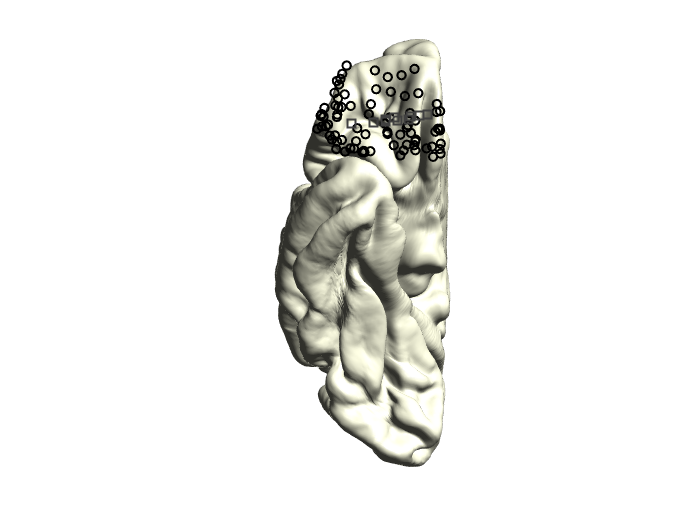

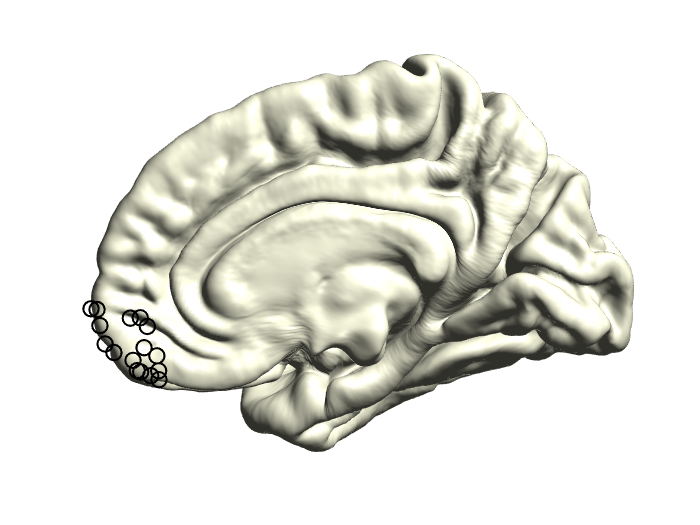

observation 1 of 107
observation 5 of 107
observation 14 of 107
observation 13 of 107
observation 12 of 107
observation 11 of 107
observation 10 of 107
observation 9 of 107
observation 59 of 107
observation 58 of 107
observation 57 of 107
observation 82 of 107
observation 81 of 107
observation 97 of 107
observation 104 of 107
observation 107 of 107
observation 2 of 107
observation 20 of 107
observation 19 of 107
observation 18 of 107
observation 17 of 107
observation 16 of 107
observation 15 of 107
observation 74 of 107
observation 73 of 107
observation 72 of 107
observation 92 of 107
observation 91 of 107
observation 102 of 107
observation 3 of 107
observation 26 of 107
observation 25 of 107
observation 24 of 107
observation 23 of 107
observation 22 of 107
observation 21 of 107
observation 77 of 107
observation 76 of 107
observation 75 of 107
observation 86 of 107
observation 85 of 107
observation 101 of 107
observation 4 of 107
observation 32 of 107
observation 31 of 107
observation 

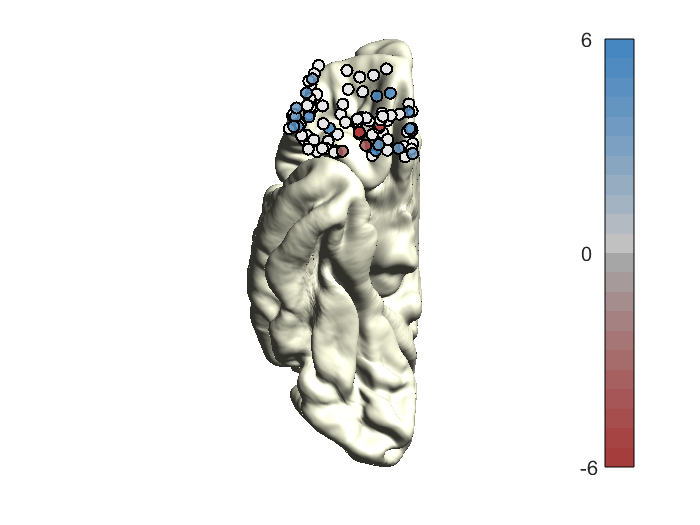

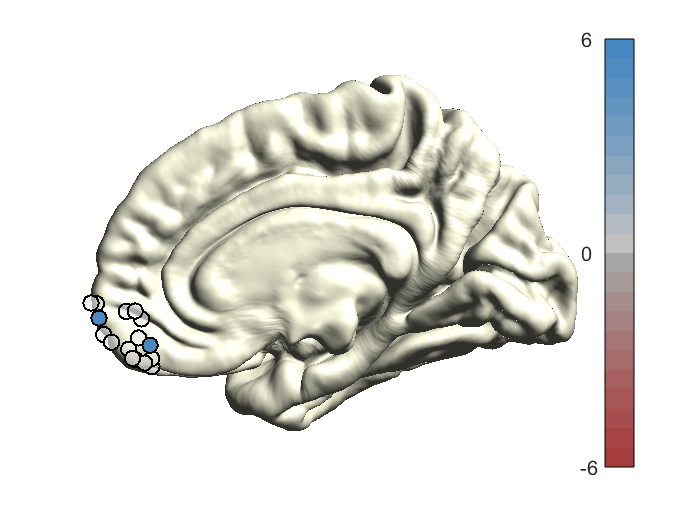

observation 1 of 146
observation 8 of 146
observation 17 of 146
observation 16 of 146
observation 15 of 146
observation 14 of 146
observation 13 of 146
observation 12 of 146
observation 11 of 146
observation 10 of 146
observation 9 of 146
observation 84 of 146
observation 83 of 146
observation 82 of 146
observation 81 of 146
observation 114 of 146
observation 113 of 146
observation 129 of 146
observation 135 of 146
observation 141 of 146
observation 2 of 146
observation 26 of 146
observation 25 of 146
observation 24 of 146
observation 23 of 146
observation 22 of 146
observation 21 of 146
observation 20 of 146
observation 19 of 146
observation 18 of 146
observation 100 of 146
observation 99 of 146
observation 98 of 146
observation 97 of 146
observation 122 of 146
observation 121 of 146
observation 132 of 146
observation 140 of 146
observation 3 of 146
observation 35 of 146
observation 34 of 146
observation 33 of 146
observation 32 of 146
observation 31 of 146
observation 30 of 146
obser

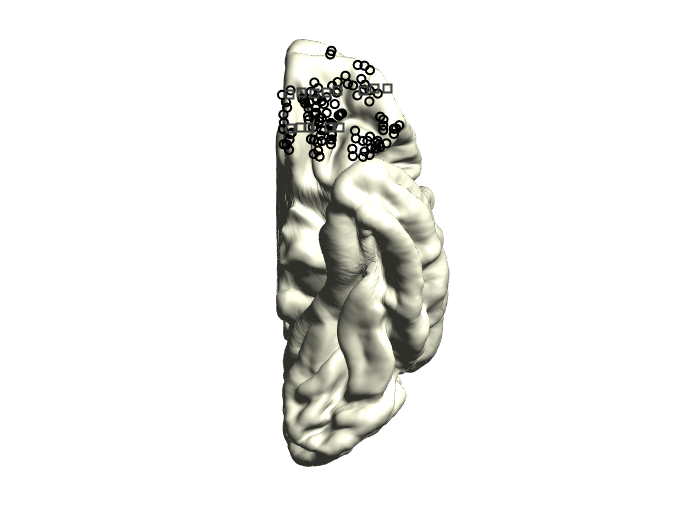

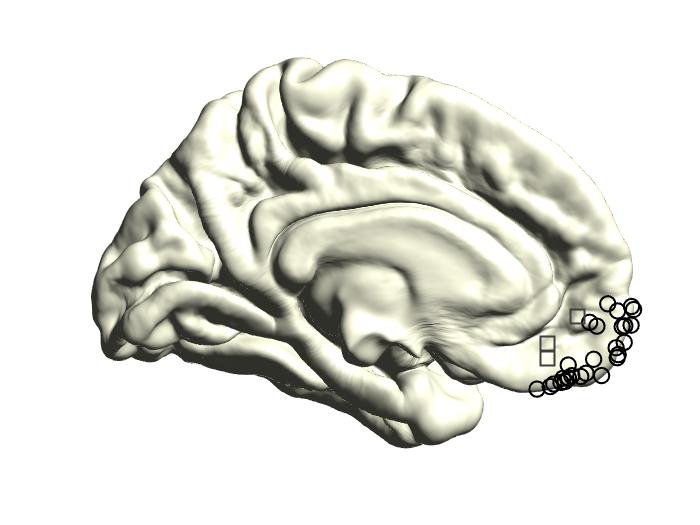

observation 1 of 146
observation 2 of 146
observation 3 of 146
observation 4 of 146
observation 5 of 146
observation 6 of 146
observation 7 of 146
observation 8 of 146
observation 17 of 146
observation 16 of 146
observation 15 of 146
observation 14 of 146
observation 13 of 146
observation 12 of 146
observation 11 of 146
observation 10 of 146
observation 9 of 146
observation 84 of 146
observation 83 of 146
observation 82 of 146
observation 81 of 146
observation 114 of 146
observation 113 of 146
observation 130 of 146
observation 138 of 146
observation 146 of 146
observation 26 of 146
observation 25 of 146
observation 24 of 146
observation 23 of 146
observation 22 of 146
observation 21 of 146
observation 20 of 146
observation 19 of 146
observation 18 of 146
observation 92 of 146
observation 91 of 146
observation 90 of 146
observation 89 of 146
observation 118 of 146
observation 117 of 146
observation 129 of 146
observation 137 of 146
observation 144 of 146
observation 35 of 146
observati

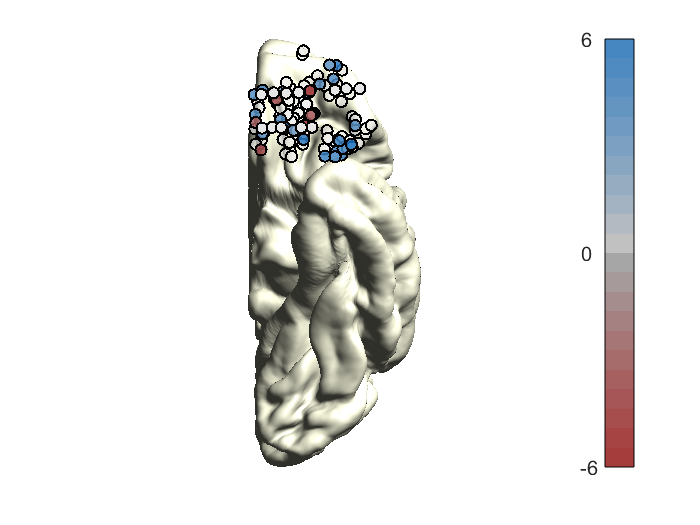

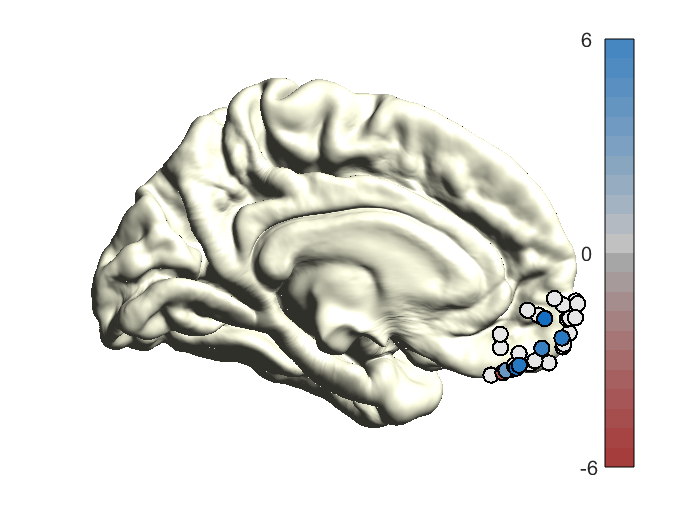

R = resultiEEG(data, 'data\BHV.json', 'data\FrontalEcogvsSeeg.json'); % cerate an instance of resultiEEG object 
% define the colors for electrode activity in hex
col = ["#0065C1",... blue for self-referential 
        "#A63838" ]; % red for math 
R.LocalizeSelfMath(col);

{
  "mdl": {
    "Estimate": [
      1.4001859598467841,
      0.36092406785367592,
      -0.59610975341093164,
      1.1318228495709413,
      -1.0779223292699258
    ],
    "SE": [
      0.16350566380237003,
      0.16710729372121758,
      0.34402941376895113,
      0.427348999495416,
      0.47381884588116063
    ],
    "DF": [
      18,
      18,
      18,
      18,
      18
    ],
    "tStat": [
      8.5635318513442726,
      2.1598343185175373,
      -1.7327290329055316,
      2.6484743170273455,
      -2.2749671918712187
    ],
    "pValue": [
      9.172853627117802E-8,
      0.044522439673817832,
      0.10024229442709157,
      0.01634148243299248,
      0.035372434007108863
    ],
    "Lower": [
      1.0566733070601437,
      0.00984467138973727,
      -1.3188887312893245,
      0.23399591765606609,
      -2.0733787856632273
    ],
    "Upper": [
      1.7436986126334244,
      0.71200346431761452,
      0.12666922446746109,
      2.0296497814858165,
      -0.082465872876

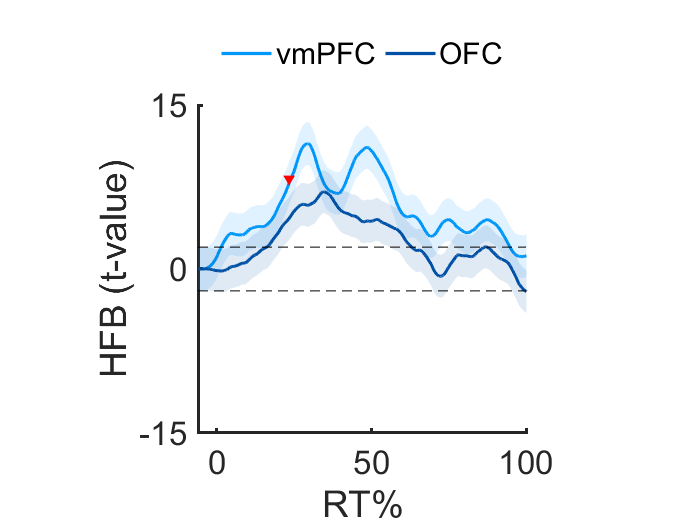

% read the time warped HFB envelope
HFB_tw.data  = R.getTimeWarppedHFB('data\Stimlock-TimeWarped_ieeg.dat');
% read labels 
HFB_tw.label = readtable('data\Stimlock-TimeWarped.tsv', FileType = 'text');
% trials were warped to 0:100% of RT 
HFB_tw.time  = R.getTimeWarppedHFB('data\Stimlock-TimeWarped_time.dat'); % pre = 500ms, fsamp = 512
% define colors 
col = ["#0097FB", "#0051A6"]; % light and dark blue 
mdl1 = R.plot_HFB(HFB_tw, .1, col); % smoothing .1s 

Now let's compare the hardwares (ECoG vs SEEG). Find one electrode pre type that are close in space and plot SNR, defined as the peak of baseline corrected signal during 800 to 1800.

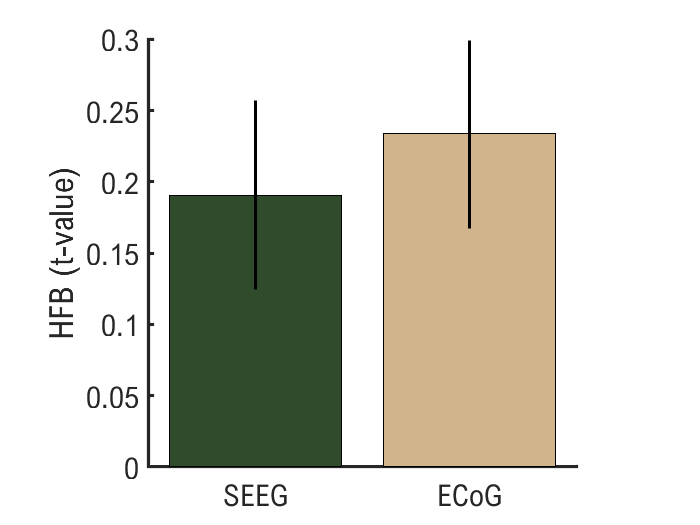

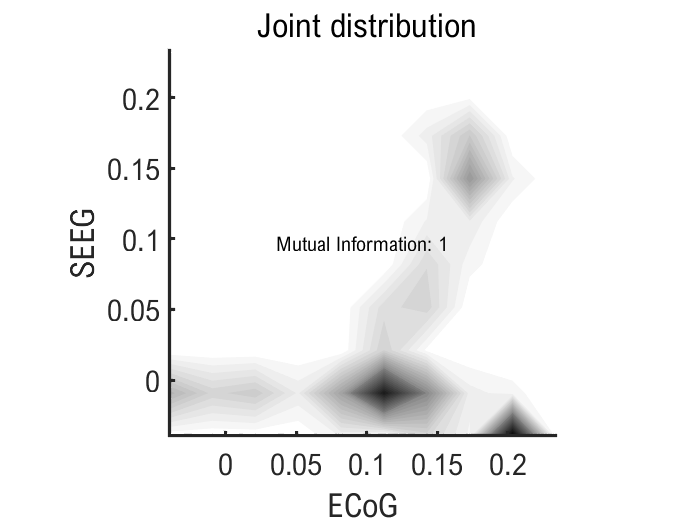

ans = 1.0232

figure
R.plotHrdWr(HFB_tw, .1, ["#2F4B2C", "#D2B48C"])

Testing if in the same brain a pattern similar to group level can be found. Therefore, we need to first find individuals with electrode implanted both in OFC and vmPFC. 

[SE, SJ] = R.find_sameBrain(HFB_tw.label, HFB_tw.data, HFB_tw.time); % finds data from same brains
t2p = time2peak(SE, SJ, mdl1) % create time2peak object 

t2p =   time2peak with properties:

                       SE: [14×18 table]
                       SJ: [14×18 table]
                      mdl: [1×1 LinearMixedModel]
    HFB_response_latencey: [1×1 struct]


Peaks were identified using matlab findpeaks, the first peak identified as the peak that had an amplitude larger than 97.5th percentile and the latency larger 10% of RT.

ti = t2p.HFB_response_latencey(); % calculate the response latency for HFB in the same brains

ti.rtp

ans = struct with fields:
     OFC: [7×1 double]
    MPFC: [7×1 double]


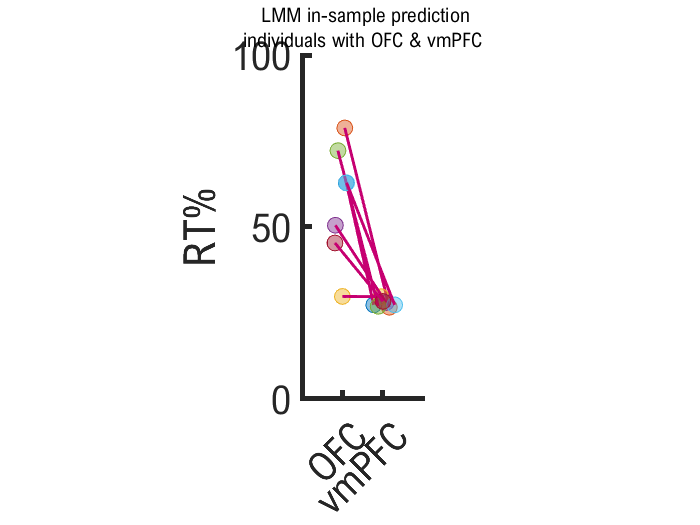

% ploting the results (fig1c)
figure
t2p.plot()

fprintf('LMM indicated that %d out of %d patients with electrodes in both sites that vmPFC was faster.\n', ...
    sum(ti.rtp.MPFC<ti.rtp.OFC), length(ti.rtp.MPFC))

LMM indicated that 7 out of 7 patients with electrodes in both sites that vmPFC was faster.


% run a binomail test
[pvalue, stats] = stat.binomtest(sum(ti.rtp.MPFC<ti.rtp.OFC), length(ti.rtp.MPFC), .5)

pvalue = 0.0082

stats = 2.6458

Now we assess how many percentages of the electrodes were activated during self-referential vs. math.

out = report.report("active_total"); % how many electrodes were activated per each condition: self > math -> self, self < math -> math, self = math -> not selective  
fprintf('total of %1.0f(%1.0f)%% self-activated\n', mean(cellfun(@(x) x.self, out))*1e2, std(cellfun(@(x) x.self, out))*1e2)

total of 13(15)% self-activated


fprintf('total of %1.0f(%1.0f)%% math\n', mean(cellfun(@(x) x.math, out))*1e2, std(cellfun(@(x) x.math, out))*1e2)

total of 4(5)% math


Performing a paired t-test to assess if the difference between the percentage of self- vs. math-activated electrodes are statistically meaningful. 

% calculate two-ways, paired t-test to compare the percentages of self- vs. math-activated electrodes  
[~, p, CI, stats ] = ttest(cellfun(@(x) x.self, out), cellfun(@(x) x.math, out));
fprintf('self > math: t(%d) = %1.2f, p < %1.2f, CI = [%1.2f, %1.2f]', stats.df, stats.tstat, p, CI)

self > math: t(21) = 2.80, p < 0.01, CI = [0.02, 0.16]

We further assess if the self-episodic and self-judgment electrodes within the self-referentially activated populations overlaps. 

out = report.report("percentage");
fprintf('total of %1.0f(%1.0f)%% within self-referental populations weer activated both in EP(SE) and SJ\n', nanmean(cell2mat(out.both))*1e2, nanstd(cell2mat(out.both))*1e2)

total of 3(7)% within self-referental populations weer activated both in EP(SE) and SJ


A little anatomical overlap found between self-episodic and self-judgment within self-referentially activated populations.

### Performing a linear-mixed effect model (LMM) to follow up if HFB differes for SE and SJ

% create a LMM object for SE and SJ
L_SEvsSJ = stat.LMMSESJ(R.data, 'Tval ~ -1 + task:JPAnatomy + (1+JPAnatomy|subj) + (1|Density)') 

L_SEvsSJ = preprocssing the input table...
finding self-referentially activated electrodes for this analysis.
removing non-self-referentially activated electrodes
done!
  LMMSESJ with properties:

         coeff: []
        coeffl: []
        coeffh: []
    prediction: []
         index: []
      preprocT: [180×19 table]
          data: [1265×15 table]
         model: "Tval ~ -1 + task:JPAnatomy + (1+JPAnatomy|subj) + (1|Density)"
           mdl: []
         dummy: 'full'


% running bootstarping in parallel
L_SEvsSJ = L_SEvsSJ.bootstramp(L_SEvsSJ.preprocT);

preprocssing the input table...
finding self-referentially activated electrodes for this analysis.
removing non-self-referentially activated electrodes
done!
Bootstrapping, please wait...
iteration : 8
iteration : 1
iteration : 1
iteration : 1
iteration : 1
iteration : 1
iteration : 1
iteration : 1
iteration : 1
See http://www.fieldtriptoolbox.org/faq/should_i_add_fieldtrip_with_all_subdirectories_to_my_matlab_path/
iteration : 2
See http://www.fieldtriptoolbox.org/faq/should_i_add_fieldtrip_with_all_subdirectories_to_my_matlab_path/
iteration : 2
See http://www.fieldtriptoolbox.org/faq/should_i_add_fieldtrip_with_all_subdirectories_to_my_matlab_path/
iteration : 2
Warni

ploting the LMM results for SE and SJ among those that showed more activity than distractor condition:

task_EP:JPAnatomy_MPFC
task_SJ:JPAnatomy_MPFC
task_EP:JPAnatomy_OFC
task_SJ:JPAnatomy_OFC


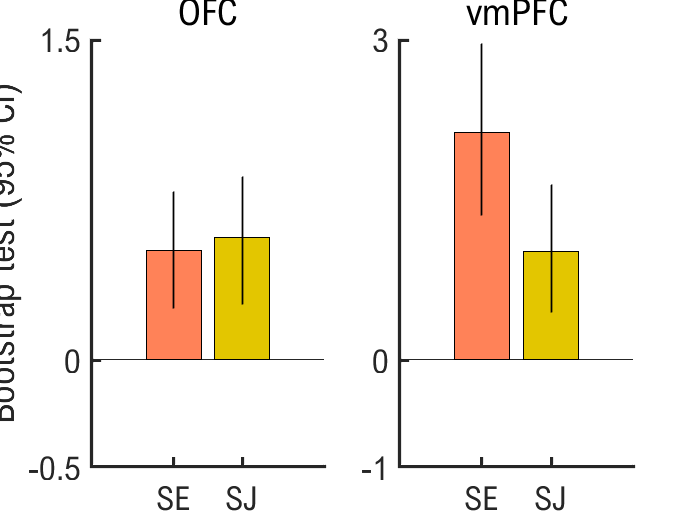

L_SEvsSJ = preprocssing the input table...
finding self-referentially activated electrodes for this analysis.
removing non-self-referentially activated electrodes
done!
  LMMSESJ with properties:

         coeff: []
        coeffl: []
        coeffh: []
    prediction: []
         index: [1×1 struct]
      preprocT: [180×19 table]
          data: [1265×15 table]
         model: "Tval ~ -1 + task:JPAnatomy + (1+JPAnatomy|subj) + (1|Density)"
           mdl: [1000×1 struct]
         dummy: 'full'


L_SEvsSJ = L_SEvsSJ.bars()

% write the report to file 
L_SEvsSJ.report('LMMSESJ')

writing the results to file:: results\LMMSESJ_bootResult.txt
done!


Now assessing if similar pattern can be found in the same brains. We identify individuals with electrodes in both OFC and vmPFC and assess how the predicted HFB value changes within same brain

L_SEvsSJ     = L_SEvsSJ.predict; %  predict the effects using the fitted LMM model 

preprocssing the input table...
finding self-referentially activated electrodes for this analysis.
removing non-self-referentially activated electrodes
done!
preprocssing the input table...
finding self-referentially activated electrodes for this analysis.
removing non-self-referentially activated electrodes
done!
preprocssing the input table...
finding self-referentially activated electrodes for this analysis.
removing non-self-referentially activated electrodes
done!
preprocssing the input table...
finding self-referentially activated electrodes for this analysis.
removing non-self-referentially activated electrodes
done!
preprocssing the input table...
finding self-referentially activated electrodes for this analysis.
removing non-self-referentially activated electrodes
done!
preprocssing the input table...
finding self-referentially activated electrodes for this analysis.
removing non-self-referentially activated electrodes
done!
preprocssing the input table...
finding self-referen

T = L_SEvsSJ.preprocT; % store the preprocessed table into T

preprocssing the input table...
finding self-referentially activated electrodes for this analysis.
removing non-self-referentially activated electrodes
done!


T.Tval_pred  = L_SEvsSJ.prediction.coeff; % add LMM predition to the table
T.Tval_predL = L_SEvsSJ.prediction.coeffl; % add LMM low boundary predition to the table 
T.Tval_predH = L_SEvsSJ.prediction.coeffh; % add LMM high boundary predition to the table 
[SE ,SJ]     = resultiEEG.find_sameBrain(T);

valm =     2.1143
    2.2063
    2.0756
    2.2623
    2.0575


valo =     0.4014
    0.7608
    0.0736
    0.9448
    0.5237


valml =     0.3340
    0.3238
    0.1772
    0.3465
    0.0730


valol =    -1.0554
   -0.6096
   -1.3253
   -0.3939
   -1.2575


valmh =     3.8945
    4.0888
    3.9739
    4.1781
    4.0420


valoh =     1.8583
    2.1313
    1.4725
    2.2836
    2.3049


subjm = 5×1 cell array
    {'S04'}
    {'S07'}
    {'S08'}
    {'S15'}
    {'S20'}


subjo = 5×1 cell array
    {'S04'}
    {'S07'}
    {'S08'}
    {'S15'}
    {'S20'}


valm =     1.0006
    1.0926
    0.9619
    1.1487
    0.9439


valo =     0.4522
    0.8116
    0.1243
    0.9956
    0.5744


valml =    -0.6078
   -0.6180
   -0.7646
   -0.5953
   -0.8688


valol =    -1.0251
   -0.5793
   -1.2950
   -0.3636
   -1.2272


valmh =     2.6090
    2.8033
    2.6884
    2.8926
    2.7565


valoh =     1.9295
    2.2024
    1.5437
    2.3548
    2.3761


subjm = 5×1 cell array
    {'S04'}
    {'S07'}
    {'S08'}
    {'S15'}
    {'S20'}


subjo = 5×1 cell array
    {'S04'}
    {'S07'}
    {'S08'}
    {'S15'}
    {'S20'}


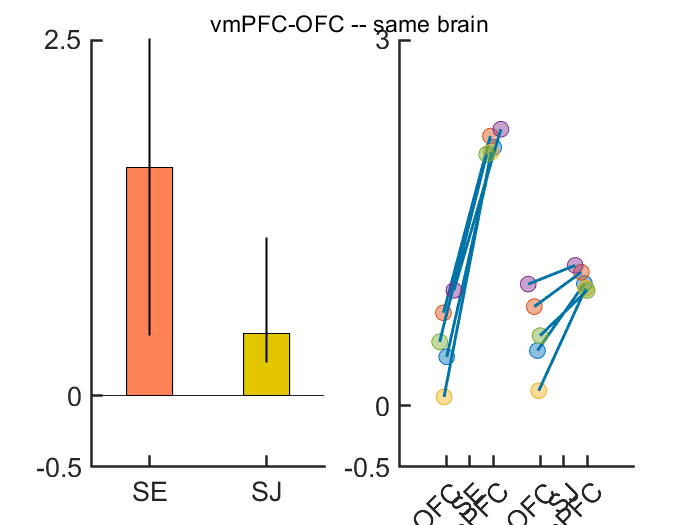

% ploting the result
col = stat.LMMSESJ.colors([1,3], 1); % get two colors with no reptitions
misc.plot_Fig1E(SE, SJ, col)

It was suggested that the medial and lateral would be different. We used another LMM to test it.

% prepare data
tmpdat = R.data;
tmpdat.absX = abs(tmpdat.X)>25; % just the lateral vs. medial. no effect of hemisphere 

LatOrMed_SEvsSJ = stat.LMMSESJ(tmpdat, 'Tval ~ 1 + absX + (1|subj) + (1|Density)', 'reference') 

LatOrMed_SEvsSJ = preprocssing the input table...
finding self-referentially activated electrodes for this analysis.
removing non-self-referentially activated electrodes
done!
  LMMSESJ with properties:

         coeff: []
        coeffl: []
        coeffh: []
    prediction: []
         index: []
      preprocT: [180×20 table]
          data: [1265×16 table]
         model: "Tval ~ 1 + absX + (1|subj) + (1|Density)"
           mdl: []
         dummy: 'reference'


LatOrMed_SEvsSJ = LatOrMed_SEvsSJ.bootstramp(LatOrMed_SEvsSJ.preprocT);

preprocssing the input table...
finding self-referentially activated electrodes for this analysis.
removing non-self-referentially activated electrodes
done!
Bootstrapping, please wait...
iteration : 9
iteration : 126
iteration : 126
iteration : 126
iteration : 126
iteration : 126
iteration : 126
iteration : 126
iteration : 126
iteration : 127
iteration : 128
iteration : 129
iteration : 130
iteration : 131
iteration : 132
iteration : 127
iteration : 128
iteration : 129
iteration : 130
iteration : 127
iteration : 128
iteration : 129
iteration : 130
iteration : 131
iteration : 132
iteration : 127
iteration : 128
iteration : 129
iteration : 130
iteration : 131
iteration : 132
iteration : 127
iteration : 128
iteration : 129
iteration : 130
iteration : 131
iteration : 132
iteration : 127
iteration : 128
iteration : 127
iteration : 128
iteration : 129
iteration : 130
iteration : 131
iteration : 132
iteration : 127
iteration : 128
iteration : 129
iteration : 130
iteration : 131
iteration : 13

supp = stat.supplmentary(LatOrMed_SEvsSJ);
supp.report()

(Intercept): 0.95 +/- 0.95 ci = [0.63, -0.61], p = 0.000999
absX_1: 0.23 +/- 0.23 ci = [-0.11, 0.13], p = 0.106


### **Self-coherence and Connotation modulate Rostral Prefrontal Cortex Self-Referential Processing **

Testing whether the self-coherece vs. sefl-incoherence modulate HFB in the OFC vs. vmPFC

clear stat
% read data with a new define trial based on patients response (true and false)
data_SCoh = readtable('StimLock_TrFl.tsv', FileType='text'); % reading the tabular data
% create a new LMM object for self-coherence vs. self-incoherence
L_CohvsInCoh = stat.LMMTrFl(data_SCoh, 'Tval ~ -1 + task:JPAnatomy + (1+JPAnatomy|subj) + (1|Density)')   

L_CohvsInCoh = preprocssing the input table...
done!
  LMMTrFl with properties:

       index: []
    preprocT: [506×15 table]
        data: [506×12 table]
       model: "Tval ~ -1 + task:JPAnatomy + (1+JPAnatomy|subj) + (1|Density)"
         mdl: []
       dummy: 'full'


L_CohvsInCoh.number_trials_preConds;

preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
number of true trials = 490.
preprocssing the input table...
done!
preprocssing the input table...
done!
number of false trials = 326.


% running bootstarping
L_CohvsInCoh = L_CohvsInCoh.bootstramp(L_CohvsInCoh.preprocT)

preprocssing the input table...
done!
Bootstrapping, please wait...
iteration : 10
iteration : 251
iteration : 258
iteration : 258
iteration : 258
iteration : 244
iteration : 245
iteration : 229
iteration : 259
iteration : 251
iteration : 252
iteration : 253
iteration : 254
iteration : 259
iteration : 260
iteration : 261
iteration : 259
iteration : 260
iteration : 261
iteration : 259
iteration : 260
iteration : 261
iteration : 246
iteration : 247
iteration : 248
iteration : 230
iteration : 231
iteration : 232
iteration : 260
iteration : 261
iteration : 262
iteration : 252
iteration : 253
iteration : 254
iteration : 255
iteration : 256
iteration : 257
iteration : 262
iteration : 263
iteration : 264
iteration : 262
iteration : 263
iteration : 264
iteration : 262
iteration : 263
iteration : 264
iteration : 233
iteration : 234
iteration : 235
iteration : 263
iteration : 264
iteration : 265
iteration : 255
iteration : 256
iteration : 257
iteration : 258
iteration : 259
iteration : 260
itera

L_CohvsInCoh = preprocssing the input table...
done!
  LMMTrFl with properties:

       index: []
    preprocT: [506×15 table]
        data: [506×12 table]
       model: "Tval ~ -1 + task:JPAnatomy + (1+JPAnatomy|subj) + (1|Density)"
         mdl: [1000×1 struct]
       dummy: 'full'


Plotting the result as a bar graph

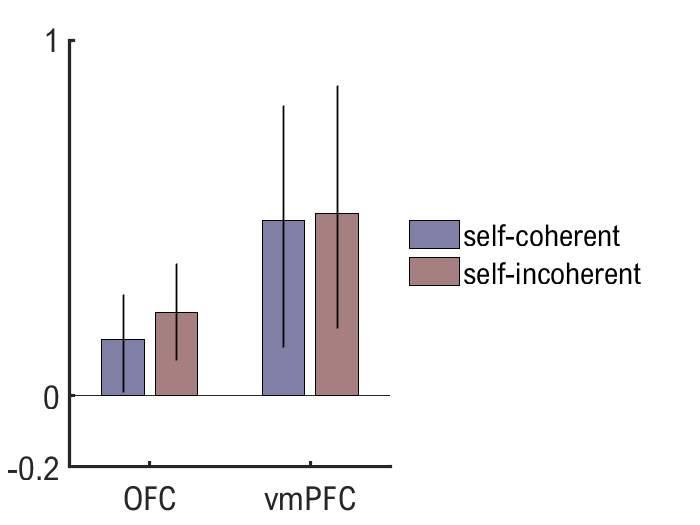

L_CohvsInCoh = preprocssing the input table...
done!
  LMMTrFl with properties:

       index: [1×1 struct]
    preprocT: [506×15 table]
        data: [506×12 table]
       model: "Tval ~ -1 + task:JPAnatomy + (1+JPAnatomy|subj) + (1|Density)"
         mdl: [1000×1 struct]
       dummy: 'full'



L_CohvsInCoh = L_CohvsInCoh.bars

% write the report to file 
L_CohvsInCoh.report('LMMSCohSInCoh')

writing the results to file:: results\LMMSCohSInCoh_bootResult.txt
done!


We further assess if the valence of the stimuli and response alter the HBF in OFC and vmPFC  

% read data with a new define trial based on patients response (true and false)
data_PoNe = readtable('data\StimLock_PoNe.tsv', FileType='text'); % reading the tabular data
% do not exclude BDI ==  0
% % data_PoNe(data_PoNe.BDI==0,:) = [];

% create a new LMM object for poisitve vs. negative
L_PovsNe = stat.LMMPoNe(data_PoNe, 'Tval ~ -1 + task:JPAnatomy + (1+JPAnatomy|subj) + (1|Density)'); 
L_PovsNe.number_trials_preConds

preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
number of minusone trials = 106.
preprocssing the input table...
done!
preprocssing the input table...
done!
number of one trials = 326.


ans = struct with fields:
    minusone: 106
         one: 326


plot the t-values with violin plot

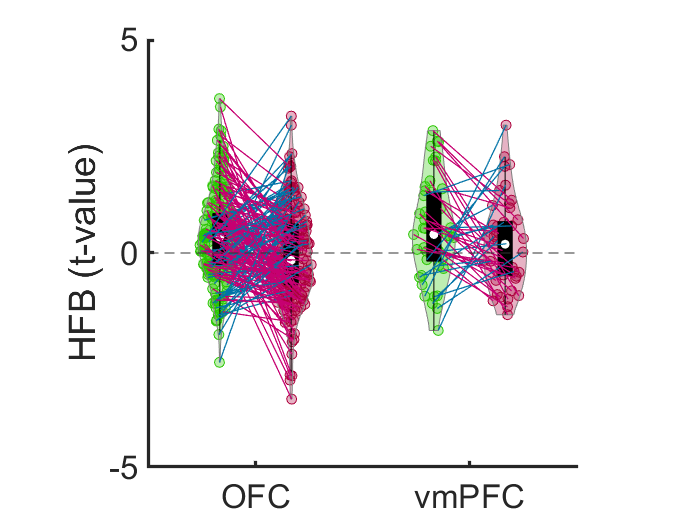

preprocssing the input table...
done!


ans = preprocssing the input table...
done!
  LMMPoNe with properties:

       index: []
    preprocT: [488×18 table]
        data: [488×14 table]
       model: "Tval ~ -1 + task:JPAnatomy + (1+JPAnatomy|subj) + (1|Density)"
         mdl: []
       dummy: 'full'


figure
L_PovsNe.violin()

Now running the LMM model 

% running bootstarping
L_PovsNe = L_PovsNe.bootstramp(L_PovsNe.preprocT)

preprocssing the input table...
done!
Bootstrapping, please wait...
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).
iteration : 17
iteration : 1
iteration : 1
iteration : 1
iteration : 1
iteration : 1
iteration : 1
iteration : 1
iteration : 1
See http://www.fieldtriptoolbox.org/faq/should_i_add_fieldtrip_with_all_subdirectories_to_my_matlab_path/
iteration : 2
See http://www.fieldtriptoolbox.org/faq/should_i_add_fieldtrip_with_all_subdirectories_to_my_matlab_path/
iteration : 2
See http://www.fieldtriptoolbox.org/faq/should_i_add_fieldtrip_with_all_subdirectories_to_my_matlab_path/
iteration : 2
Warnin

L_PovsNe = preprocssing the input table...
done!
  LMMPoNe with properties:

       index: []
    preprocT: [488×18 table]
        data: [488×14 table]
       model: "Tval ~ -1 + task:JPAnatomy + (1+JPAnatomy|subj) + (1|Density)"
         mdl: [1000×1 struct]
       dummy: 'full'


plot the LMM coefficients in a bar garph 

ans = 0.1281

ans = 0.1967

ans = 0.3277

ans = 0.3320

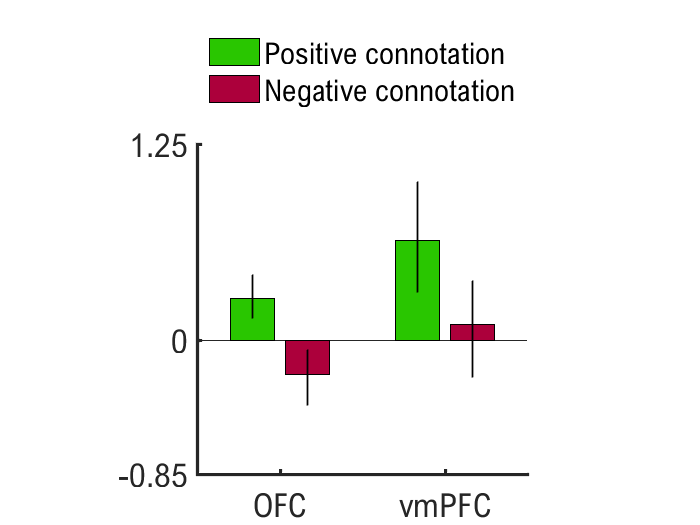

L_PovsNe = preprocssing the input table...
done!
  LMMPoNe with properties:

       index: [1×1 struct]
    preprocT: [488×18 table]
        data: [488×14 table]
       model: "Tval ~ -1 + task:JPAnatomy + (1+JPAnatomy|subj) + (1|Density)"
         mdl: [1000×1 struct]
       dummy: 'full'


L_PovsNe = L_PovsNe.bars() % bar plot the LMM coefficients 

% write stats to file
L_PovsNe.report('L_PovsNe')

writing the results to file:: results\L_PovsNe_bootResult.txt
done!


Let's assess if the level of depression and tasks are realte to HFB in OFC and vmpFC

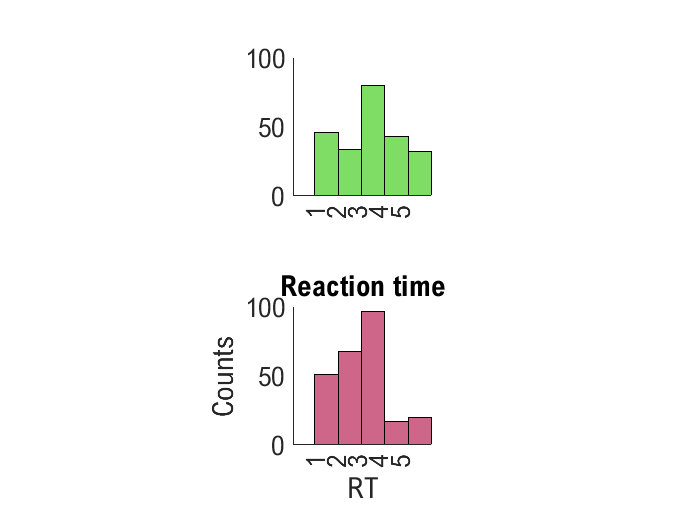

supp = stat.supplmentary(L_PovsNe);
% plotting the histogram of RT as function of pos vs. neg
supp.histg('RT','task')
title('Reaction time')
print -dpng -r300 results\RT--connotations.png

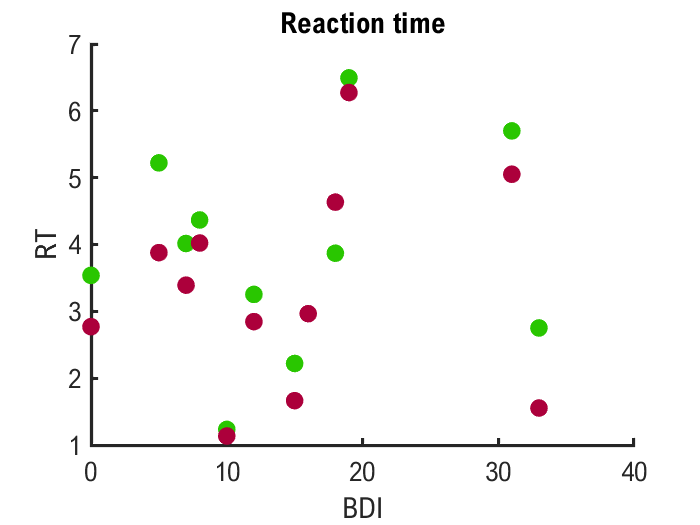

supp.scatterg('BDI', 'RT', 'task')
title('Reaction time')
print -dpng -r300 results\RT--connotations.png

supp.stat('RT ~ 1 + BDIz*task + (1|subj)')

preprocssing the input table...
done!


ans = Linear mixed-effects model fit by ML

Model information:
    Number of observations             322
    Fixed effects coefficients           4
    Random effects coefficients         12
    Covariance parameters                2

Formula:
    RT ~ 1 + task*BDIz + (1 | subj)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -125.04    -102.39    68.52            -137.04 

Fixed effects coefficients (95% CIs):
    Name                     Estimate    SE          tStat      DF     pValue        Lower       Upper   
    {'(Intercept)'  }          3.7678     0.42398     8.8868    318             0      2.9337       4.602
    {'task_one'     }        -0.46497    0.019296    -24.097    318             0    -0.50294    -0.42701
    {'BDIz'         }        0.098907      0.2851    0.34692    318       0.72888    -0.46202     0.65983
    {'task_one:BDIz'}        0.064145    0.0

supp.stat('Tval ~ 1 + BDI*hemi  + (1|subj) + (1|Density)')

preprocssing the input table...
done!


ans = Linear mixed-effects model fit by ML

Model information:
    Number of observations             322
    Fixed effects coefficients           4
    Random effects coefficients         16
    Covariance parameters                3

Formula:
    Tval ~ 1 + BDI*hemi + (1 | subj) + (1 | Density)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    941.46    967.88    -463.73          927.46  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat      DF     pValue      Lower        Upper     
    {'(Intercept)'}          0.54563      0.2431     2.2445    318    0.025487     0.067351        1.0239
    {'BDI'        }        -0.028049     0.01461    -1.9199    318    0.055767    -0.056793    0.00069502
    {'hemi_r'     }          0.48303     0.40409     1.1953    318     0.23285     -0.31201        1.2781
    {'BDI:hemi_r' }        -0.0

supp.stat('BDI ~ 1 + hemi ')

preprocssing the input table...
done!


ans = Linear mixed-effects model fit by ML

Model information:
    Number of observations             322
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    BDI ~ 1 + hemi

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    2137.3    2148.6    -1065.6          2131.3  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF     pValue     Lower       Upper 
    {'(Intercept)'}         10.99      0.46828    23.469    320          0      10.069    11.911
    {'hemi_r'     }        1.3707      0.76077    1.8017    320    0.07254    -0.12609    2.8674

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower     Upper 
    {'Res Std'}        6.6225      6.1303    7.1542


preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!


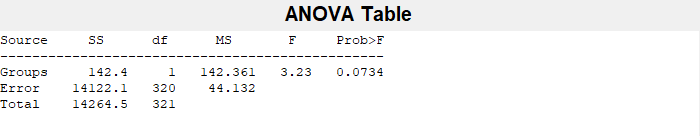

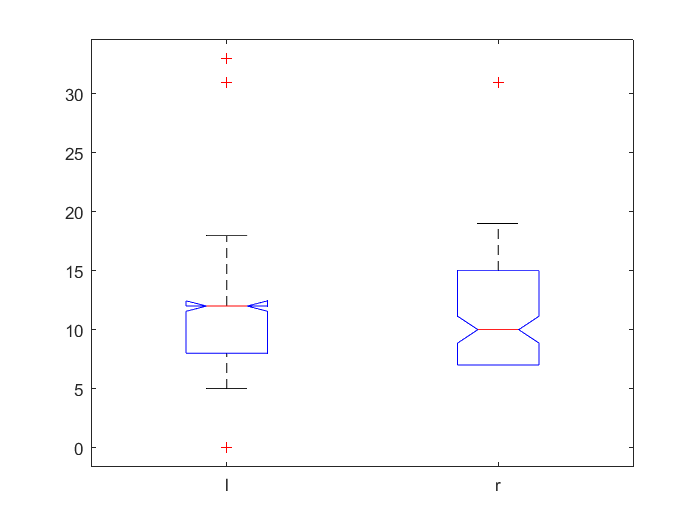

preprocssing the input table...
done!
preprocssing the input table...
done!


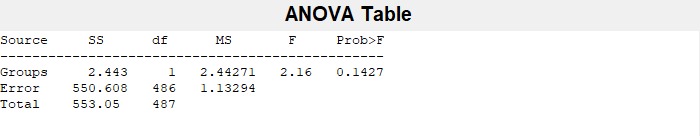

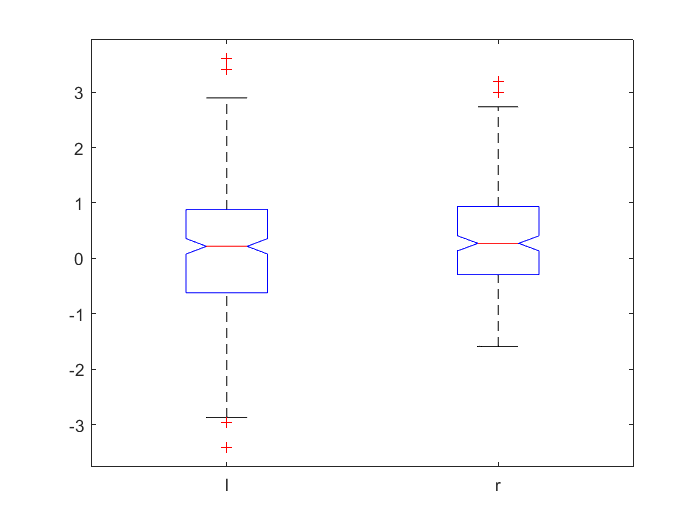

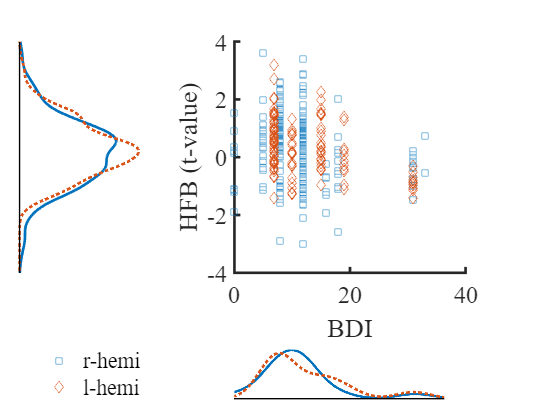

supp.scat_his()

Now we assess if there is association with BDI and the HFB in the OFC and vmPFC

% create a new LMM model with BDI predictor
% zscore BDI
data_PoNe.BDIz = (data_PoNe.BDI-nanmean(data_PoNe.BDI))./nanstd(data_PoNe.BDI);

Psych = stat.LMMPoNe(data_PoNe, 'Tval ~ -1 + BDIz:task:JPAnatomy + (1 |subj) + (1|Density)');
% fix S13_47_JT2 
% % % Psych.data.BDI(strcmp(Psych.data.subj, 'S13_47')) = 5;

% running bootstarping
Psych = Psych.bootstramp(Psych.preprocT)

preprocssing the input table...
done!
Bootstrapping, please wait...
iteration : 2
iteration : 126
iteration : 126
iteration : 126
iteration : 126
iteration : 133
iteration : 119
iteration : 133
iteration : 119
iteration : 127
iteration : 128
iteration : 129
iteration : 127
iteration : 128
iteration : 129
iteration : 127
iteration : 128
iteration : 129
iteration : 127
iteration : 128
iteration : 134
iteration : 135
iteration : 136
iteration : 120
iteration : 121
iteration : 134
iteration : 135
iteration : 136
iteration : 120
iteration : 121
iteration : 122
iteration : 130
iteration : 131
iteration : 132
iteration : 130
iteration : 131
iteration : 132
iteration : 130
iteration : 131
iteration : 132
iteration : 129
iteration : 130
iteration : 131
iteration : 132
iteration : 137
iteration : 138
iteration : 139
iteration : 122
iteration : 123
iteration : 124
iteration : 125
iteration : 137
iteration : 138
iteration : 139
iteration : 123
iteration : 124
iteration : 125
iteration : 133
iterat

Psych = preprocssing the input table...
done!
  LMMPoNe with properties:

       index: []
    preprocT: [488×18 table]
        data: [488×15 table]
       model: "Tval ~ -1 + BDIz:task:JPAnatomy + (1 |subj) + (1|Density)"
         mdl: [1000×1 struct]
       dummy: 'full'


Plotting the LMM results for neuropsych data and neural HFB measure:

ans = 0.1736

ans = 0.1448

ans = 1.0894

ans = 0.3165

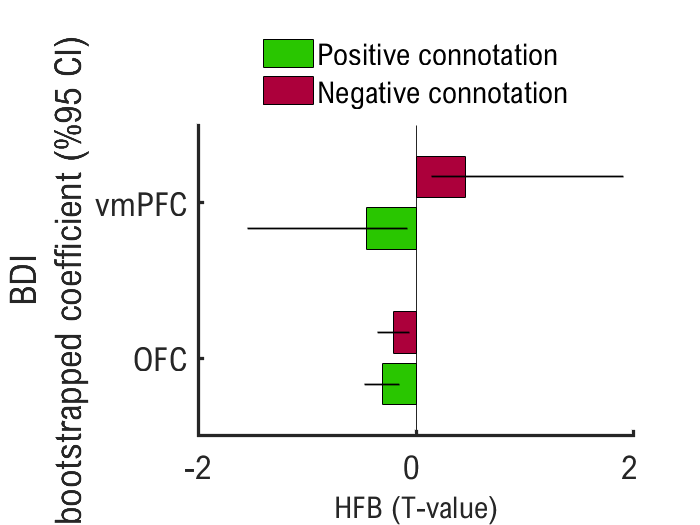

Psych = preprocssing the input table...
done!
  LMMPoNe with properties:

       index: [1×1 struct]
    preprocT: [488×18 table]
        data: [488×15 table]
       model: "Tval ~ -1 + BDIz:task:JPAnatomy + (1 |subj) + (1|Density)"
         mdl: [1000×1 struct]
       dummy: 'full'


Psych = Psych.bars('on') % plot the coefficients, horizontal layout "on" 

% write the results to a file 
Psych.report('Psych&HFA')

writing the results to file:: results\Psych&HFA_bootResult.txt
done!


We further assess the negative association between HFB in OFC and vmPFC and the psych (mood) data.

[POS, NEG, POSXNEG] = Psych.subWPoNe(); % finds subjects with both pos and neg data

preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing

[msr, BDI, b, tval] = Psych.OFCvmPFCMEASURE(POSXNEG,18); % save b for out-sample analysis, only consider those within 18 month gaps.
% plotting
[curve_score, goodness_score, output_score, Pvalue]  = Psych.plot(msr, BDI, tval, 4);
fprintf('slope = %1.2f, R2 = %1.2f, p = %1.3f, MAE = %1.0f\n', curve_score.p1, goodness_score.rsquare, Pvalue(1), mean(abs(output_score.residuals)))

slope = -14.47, R2 = 0.27, p = 0.006, MAE = 7


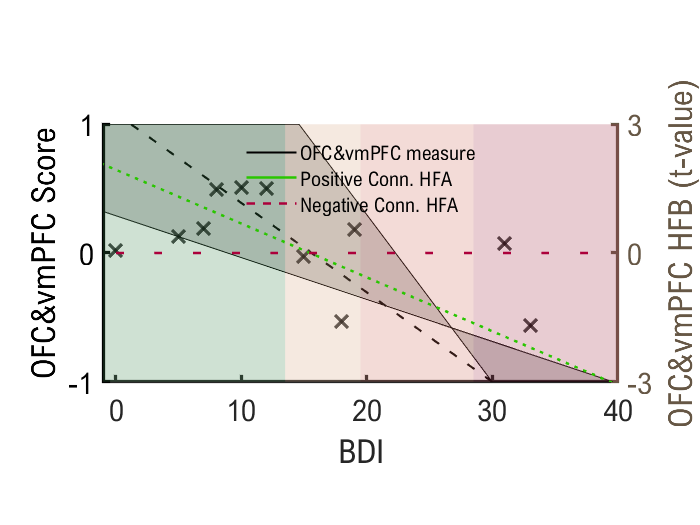

print -dpng -r300 results\FigS4.png
print -dsvg results\FigS4.svg

We got two new out-sample data. let's forecats the BDI using the OFC&vmPFC measure

preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!


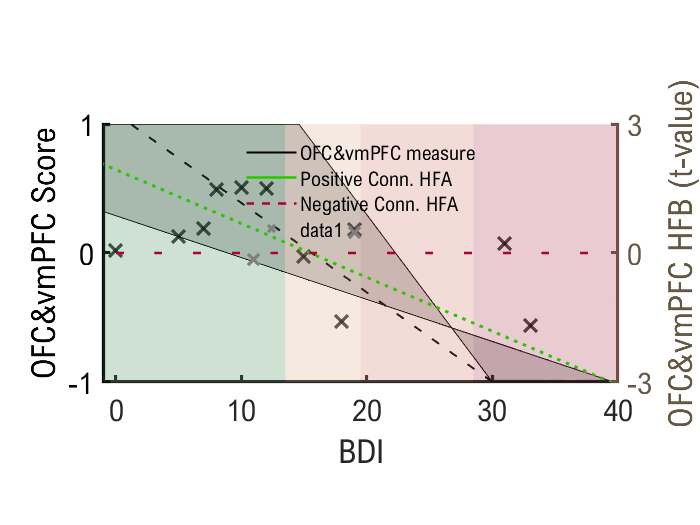

OS = readtable('data\StimLock_PoNe_Outsample.tsv', FileType='text'); % reading the tabular data
% manually add psych data
OS.BDI(strcmp(OS.subj, 'OS01')) = 19;
OS.BDI(strcmp(OS.subj, 'OS02')) = 11;
warning off
OS.DOEvsDOI(strcmp(OS.subj, 'OS01')) = days(datetime('3/31/2023') - datetime('4/11/2022'));
OS.DOEvsDOI(strcmp(OS.subj, 'OS02')) = days(datetime('5/1/2023') - datetime('7/27/2020'));
warning on
if unique(OS.DOEvsDOI(strcmp(OS.subj, 'OS01')))<36*30 && ... if the psych and iEEG is less than and 18 months
    unique(OS.DOEvsDOI(strcmp(OS.subj, 'OS02')))<36*30
LOS = stat.LMMPoNe(OS, 'Tval ~ -1 + BDIz:task:JPAnatomy + (1 |subj) + (1|Density)');
[O_POS, O_NEG, O_POSXNEG] = LOS.subWPoNe();
% forecasting
omsr_(:,1) = O_POSXNEG{1}.Tval - b.neuro(1).*double(O_POSXNEG{1}.X<0); % regress the effect of hemishphere for pos
omsr_(:,2) = O_POSXNEG{2}.Tval - b.neuro(2).*double(O_POSXNEG{2}.X<0);% regress the effect of hemishphere for neg

omsr = LOS.rescale(omsr_', 2, .5); % compute OFC&vmPFC measure
hold on
scatter([unique(OS.BDI(strcmp(OS.subj, 'OS01')))
    unique(OS.BDI(strcmp(OS.subj, 'OS02')))], omsr(1,:)', 90, 'x',...
    'MarkerEdgeColor',[.5,.5,.5], 'LineWidth', 2, 'MarkerFaceAlpha', .75)
hold off
print -dsvg results\Fig2C_outsample_Added.svg
else

   disp('The psych data and iEEG were too far apart! More than 36 months')
end

#### Controling statistic

It has been suggested to assess the effect of inclusion of the main effect for BDI and  is the model.

Importantly we hypothezied that BDI affect OFC and vmPFC in a same manner. 

mdl3 = supp.stat('Tval ~ 1 + task:BDIz:JPAnatomy  + task:BDIz + task  + (1+JPAnatomy|subj) + (1|Density)')

preprocssing the input table...
done!


mdl3 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             322
    Fixed effects coefficients           4
    Random effects coefficients         28
    Covariance parameters                5

Formula:
    Tval ~ 1 + task + task:BDIz + task:JPAnatomy:BDIz + (1 + JPAnatomy | subj) + (1 | Density)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    922.58    956.55    -452.29          904.58  

Fixed effects coefficients (95% CIs):
    Name                                   Estimate     SE         tStat       DF     pValue        Lower       Upper   
    {'(Intercept)'                }        -0.075435    0.14734    -0.51198    318       0.60902    -0.36532     0.21445
    {'task_one'                   }           0.4926    0.10707      4.6008    318    6.0863e-06     0.28195     0.70324
    {'task_one:BDIz'              }         -0.52

% read data with a new define trial based on patients response (true and false)
data_YpNpYnNn = readtable('data\StimLock_YpNpYnNn.tsv', FileType='text'); % reading the tabular data
% do not exclude BDI ==  0
% % data_PoNe(data_PoNe.BDI==0,:) = [];

% create a new LMM object for poisitve vs. negative
L_YpNpYnNn = stat.LMMYpNpYnNn(data_YpNpYnNn, 'Tval ~ -1 + task + (1+JPAnatomy|subj) + (1|Density) + (1|dof)'); 
L_YpNpYnNn.number_trials_preConds

preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
number of NoNeg trials = 120.
preprocssing the input table...
done!
preprocssing the input table...
done!
number of NoPos trials = 38.
preprocssing the input table...
done!
preprocssing the input table...
done!
number of YesNeg trials = 53.
preprocssing the input table...
done!
preprocssing the input table...
done!
number of YesPos trials = 202.


ans = struct with fields:
     NoNeg: 120
     NoPos: 38
    YesNeg: 53
    YesPos: 202


L_YpNpYnNn = L_YpNpYnNn.bootstramp(L_YpNpYnNn.preprocT)

preprocssing the input table...
done!
Bootstrapping, please wait...
iteration : 13
iteration : 626
iteration : 633
iteration : 633
iteration : 633
iteration : 619
iteration : 604
iteration : 634
iteration : 626
iteration : 627
iteration : 628
iteration : 634
iteration : 635
iteration : 634
iteration : 635
iteration : 634
iteration : 635
iteration : 620
iteration : 621
iteration : 605
iteration : 606
iteration : 635
iteration : 636
iteration : 627
iteration : 628
iteration : 629
iteration : 630
iteration : 636
iteration : 637
iteration : 636
iteration : 637
iteration : 636
iteration : 622
iteration : 623
iteration : 607
iteration : 608
iteration : 637
iteration : 638
iteration : 637
iteration : 638
iteration : 624
iteration : 625
iteration : 609
iteration : 610
iteration : 639
iteration : 640
iteration : 629
iteration : 630
iteration : 631
iteration : 632
iteration : 638
iteration : 639
iteration : 638
iteration : 639
iteration : 631
iteration : 632
iteration : 639
iteration : 633
itera

L_YpNpYnNn = preprocssing the input table...
done!
  LMMYpNpYnNn with properties:

       index: []
    preprocT: [741×18 table]
        data: [745×14 table]
       model: "Tval ~ -1 + task + (1+JPAnatomy|subj) + (1|Density) + (1|dof)"
         mdl: [1000×1 struct]
       dummy: 'full'


L_YpNpYnNn=L_YpNpYnNn.bars

ans = 0.1549

ans = 0.1997

ans = 0.3017

ans = 0.2818

L_YpNpYnNn = preprocssing the input table...
done!
  LMMYpNpYnNn with properties:

       index: [1×1 struct]
    preprocT: [741×18 table]
        data: [745×14 table]
       model: "Tval ~ -1 + task + (1+JPAnatomy|subj) + (1|Density) + (1|dof)"
         mdl: [1000×1 struct]
       dummy: 'full'


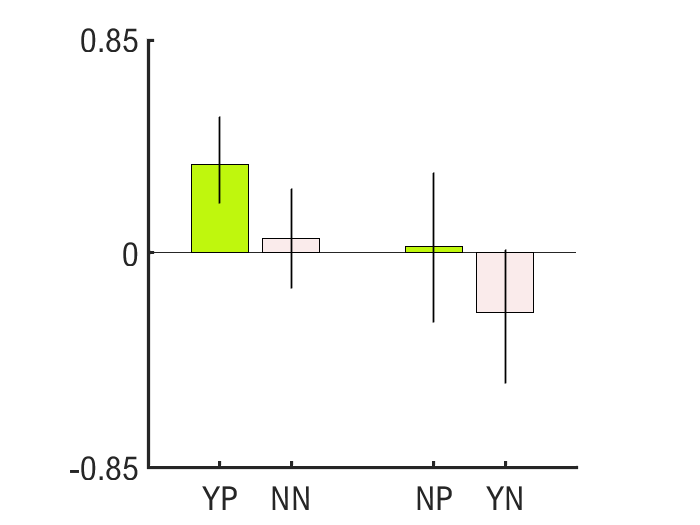

print -dsvg results\FigS.HFA.YpNn_NpYn.svg

L_YpNpYnNn.report('YpNnNpYn')

writing the results to file:: results\YpNnNpYn_bootResult.txt
done!


cf = [L_YpNpYnNn.mdl(:).cf];
df1 = round(median(cat(1,cf.df1)));
df2 = round(median(cat(1,cf.df2)));
f = median(cat(1,cf.f));
p = median(cat(1,cf.p));
for i =1:2
fprintf('F(%d,%d) = %1.2f, p = %1.2f\n', df1(i), df2(i), f(i), p(i))
end

F(1,737) = 4.60, p = 0.03
F(1,737) = 3.39, p = 0.07



supp = stat.supplmentary(L_YpNpYnNn);
mdl_supp = supp.stat('dof ~ 1 + BDI*task + (1|subj)', 'effect', false, true, true)

preprocssing the input table...
done!


mdl_supp = Linear mixed-effects model fit by ML

Model information:
    Number of observations              37
    Fixed effects coefficients           8
    Random effects coefficients         12
    Covariance parameters                2

Formula:
    dof ~ 1 + task*BDI + (1 | subj)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    170.01    186.12    -75.003          150.01  

Fixed effects coefficients (95% CIs):
    Name                       Estimate      SE          tStat       DF    pValue        Lower        Upper   
    {'(Intercept)'    }            6.3189     0.66683       9.476    29    2.2056e-10       4.9551      7.6828
    {'task_NoNeg'     }           0.31823     0.93625      0.3399    29       0.73638      -1.5966      2.2331
    {'task_NoPos'     }           -2.6232      1.3816     -1.8987    29      0.067593      -5.4488     0.20242
    {'task_YesNeg'    }

mdl_supp.anova

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue    
    {'(Intercept)'}        89.795    1      29     2.2056e-10
    {'task'       }        9.8051    3      29     0.00012546
    {'BDI'        }        1.0736    1      29        0.30869
    {'task:BDI'   }        1.3516    3      29        0.27709


As an othe control analysis we only included **Yes to Positive** and **Yes to Negative** for assessing realtionship with depression, 

data_YpYn = data_YpNpYnNn(strcmp(data_YpNpYnNn.task, 'YesPos') | strcmp(data_YpNpYnNn.task, 'YesNeg'),:);
% create the LMM object
L_YpYn = stat.LMMPoNe(data_YpYn, 'Tval ~ -1 + BDIz:task:JPAnatomy + (1 |subj) + (1|Density)'); 

% run the bootstarp 
L_YpYn = L_YpYn.bootstramp(L_YpYn.preprocT)

preprocssing the input table...
done!
Bootstrapping, please wait...
Starting parallel pool (parpool) using the 'local' profile ...


Connected to the parallel pool (number of workers: 8).
iteration : 1
iteration : 1
iteration : 1
iteration : 1
iteration : 1
iteration : 1
iteration : 1
iteration : 1
iteration : 1
See http://www.fieldtriptoolbox.org/faq/should_i_add_fieldtrip_with_all_subdirectories_to_my_matlab_path/
iteration : 2
See http://www.fieldtriptoolbox.org/faq/should_i_add_fieldtrip_with_all_subdirectories_to_my_matlab_path/
iteration : 2
See http://www.fieldtriptoolbox.org/faq/should_i_add_fieldtrip_with_all_subdirectories_to_my_matlab_path/
iteration : 2
See http://www.fieldtriptoolbox

L_YpYn = preprocssing the input table...
done!
  LMMPoNe with properties:

       index: []
    preprocT: [444×18 table]
        data: [447×14 table]
       model: "Tval ~ -1 + BDIz:task:JPAnatomy + (1 |subj) + (1|Density)"
         mdl: [1000×1 struct]
       dummy: 'full'


% plot the results 
L_YpYn = L_YpYn.bars('on')

ans = 0.1523

ans = 0.1571

ans = 1.2655

ans = 0.3681

L_YpYn = preprocssing the input table...
done!
  LMMPoNe with properties:

       index: [1×1 struct]
    preprocT: [444×18 table]
        data: [447×14 table]
       model: "Tval ~ -1 + BDIz:task:JPAnatomy + (1 |subj) + (1|Density)"
         mdl: [1000×1 struct]
       dummy: 'full'


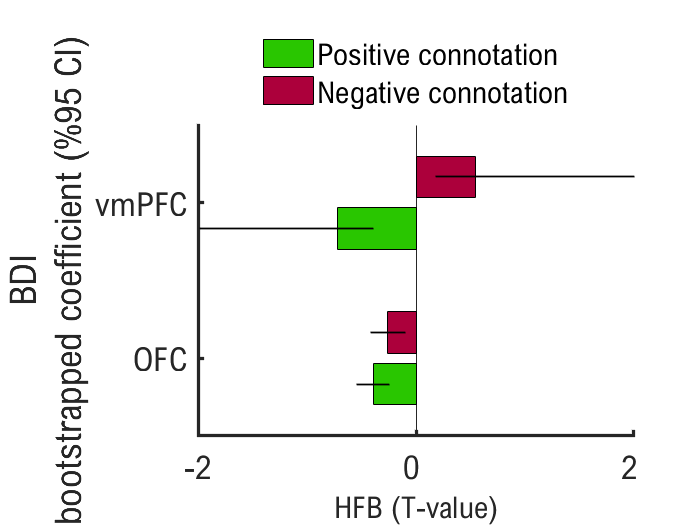

print -dsvg results\FigS.BDI_YpYn.svg

What would it be for BDI if we use only yes to pos and yes to neg:

L_YpYnPsych  = stat.LMMYpNpYnNn(L_YpYn.data, 'Tval ~ -1 + BDIz:task:JPAnatomy + (1 |subj) + (1|Density)')

L_YpYnPsych = preprocssing the input table...
done!
  LMMYpNpYnNn with properties:

       index: []
    preprocT: [444×18 table]
        data: [447×14 table]
       model: "Tval ~ -1 + BDIz:task:JPAnatomy + (1 |subj) + (1|Density)"
         mdl: []
       dummy: 'full'



[POS_YPYN, NEG_YPYN, POSXNEG_YPYN] = L_YpYnPsych.subWPoNe(); % finds subjects with both pos and neg data

preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing

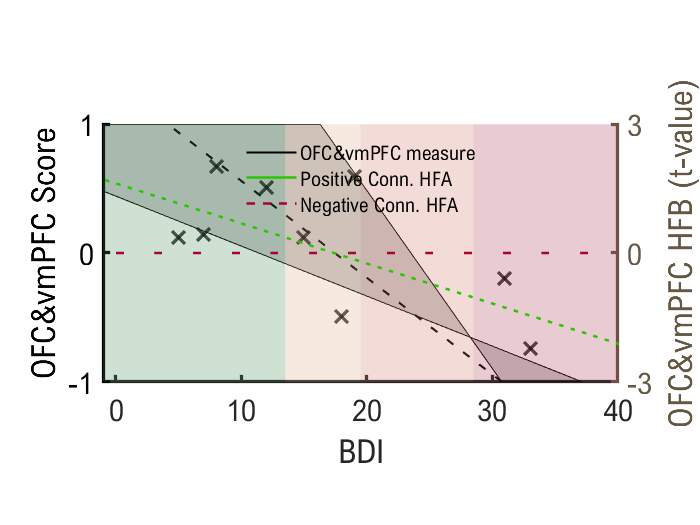

[msr_YPYN, BDI_YPYN, b_YPYN, tval_YPYN] = L_YpYn.OFCvmPFCMEASURE(POSXNEG_YPYN,18); % save b for out-sample analysis, only consider those within 18 month gaps.
% plotting
[curve_score_YPYN, goodness_score_YPYN, output_score_YPYN, Pvalue_YPYN, jk]  = L_YpYn.plot(msr_YPYN, BDI_YPYN, tval_YPYN, 4);

fprintf('slope = %1.2f, R2 = %1.2f, p = %1.3f, MAE = %1.0f\n', curve_score_YPYN.p1, goodness_score_YPYN.rsquare, Pvalue_YPYN(1), mean(abs(output_score_YPYN.residuals)))

slope = -13.38, R2 = 0.42, p = 0.003, MAE = 6


preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!


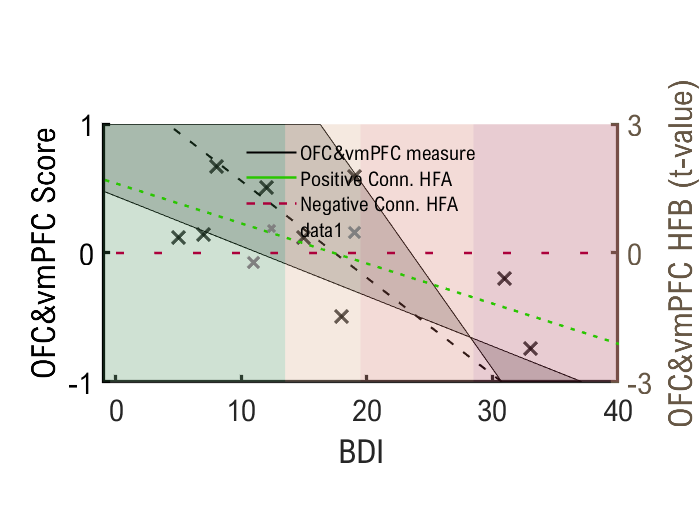

   11.1164
   20.4656




OS = readtable('data\StimLock_PoNe_Outsample.tsv', FileType='text'); % reading the tabular data
% manually add psych data
OS.BDI(strcmp(OS.subj, 'OS01')) = 19;
OS.BDI(strcmp(OS.subj, 'OS02')) = 11;
warning off
OS.DOEvsDOI(strcmp(OS.subj, 'OS01')) = days(datetime('3/31/2023') - datetime('4/11/2022'));
OS.DOEvsDOI(strcmp(OS.subj, 'OS02')) = days(datetime('5/1/2023') - datetime('7/27/2020'));
warning on
if unique(OS.DOEvsDOI(strcmp(OS.subj, 'OS01')))<36*30 && ... if the psych and iEEG is less than and 18 months
    unique(OS.DOEvsDOI(strcmp(OS.subj, 'OS02')))<36*30
LOS = stat.LMMPoNe(OS, 'Tval ~ -1 + BDIz:task:JPAnatomy + (1 |subj) + (1|Density)');
[O_POS, O_NEG, O_POSXNEG] = LOS.subWPoNe();
% forecasting
omsr_(:,1) = O_POSXNEG{1}.Tval - b_YPYN.neuro(1).*double(O_POSXNEG{1}.X<0); % regress the effect of hemishphere for pos
omsr_(:,2) = O_POSXNEG{2}.Tval - b_YPYN.neuro(2).*double(O_POSXNEG{2}.X<0);% regress the effect of hemishphere for neg

omsr = LOS.rescale(omsr_', 2, .5); % compute OFC&vmPFC measure
hold on
scatter([unique(OS.BDI(strcmp(OS.subj, 'OS01')))
    unique(OS.BDI(strcmp(OS.subj, 'OS02')))], omsr(1,:)', 90, 'x',...
    'MarkerEdgeColor',[.5,.5,.5], 'LineWidth', 2, 'MarkerFaceAlpha', .75)
hold off
print -dsvg results\Fig2C_outsample_Added.svg
disp(curve_score_YPYN(omsr(1,:)))
else

   disp('The psych data and iEEG were too far apart! More than 36 months')
end

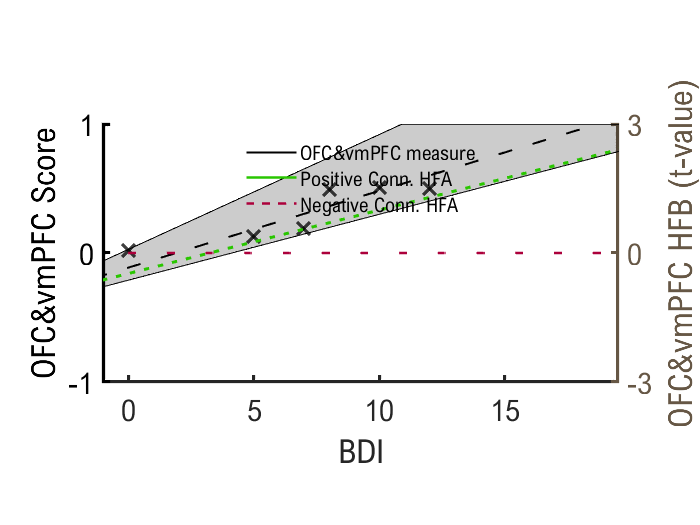

[msr, BDI, b, tval] = Psych.OFCvmPFCMEASURE(POSXNEG,6); % save b for out-sample analysis, only consider those within 18 month gaps.
% plotting
[curve_score, goodness_score, output_score, Pvalue]  = Psych.plot(msr, BDI, tval, 2, false);
print -dsvg results\FigS.OFC_vmPFCmeasure_3months.svg